# Evaluación 11.1 (Trayectorias en lazo abierto)

**Implementar** el código requerido para generar las siguientes trayectorias a partir del tiempo y de las velocidades angulares y lineales en un plano 2D, según corresponda. La altura de cada letra debe ser de **3m.**, el ancho puede ser ajustable **a criterio propio** y la separación entre cada letra debe ser de **0.5m.**

**Trayectoria a generar: A_MORELOS**

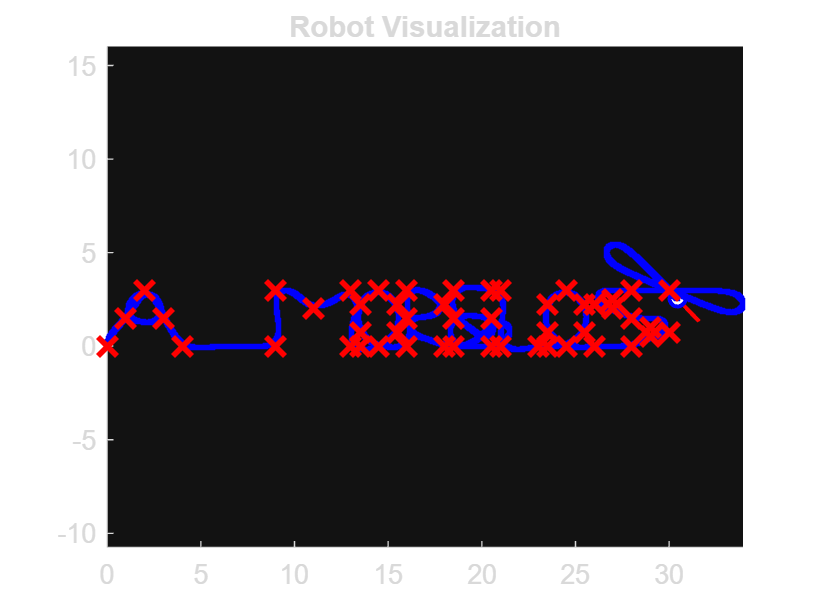

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameterss
sampleTime = 0.01;               % Sample time [s]
tVec = 0:sampleTime:110;         % Time array

initPose = [0;0;pi/2];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [0,0; 2,3; 3,1.5; 1,1.5; 2,3; 4,0; 9,0; 9,3; 11,2; 13,3; 13,0; 13.5,0; 14.5,0; 15.5,0.75; 15.5,2.25; 14.5,3; 13.5,2.25; 13.5,0.75; 14.5,0; 16,0; 16,3; 18,2.25; 16,1.5; 18,0; 18.5,0; 20.5,0; 18.5,0; 18.5,1.5; 20.5,1.5; 18.5,1.5; 18.5,3; 20.5,3; 21,3; 21,0; 23,0; 23.5,0; 24.5,0; 25.5,0.75; 25.5,2.25; 24.5,3; 23.5,2.25; 23.5,0.75; 24.5,0; 26,0; 28,0; 29,0.5; 30,0.75; 29,1; 28,1.5; 27,2; 26,2.25; 27,2.5; 28,3; 30,3];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = .8;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 5;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

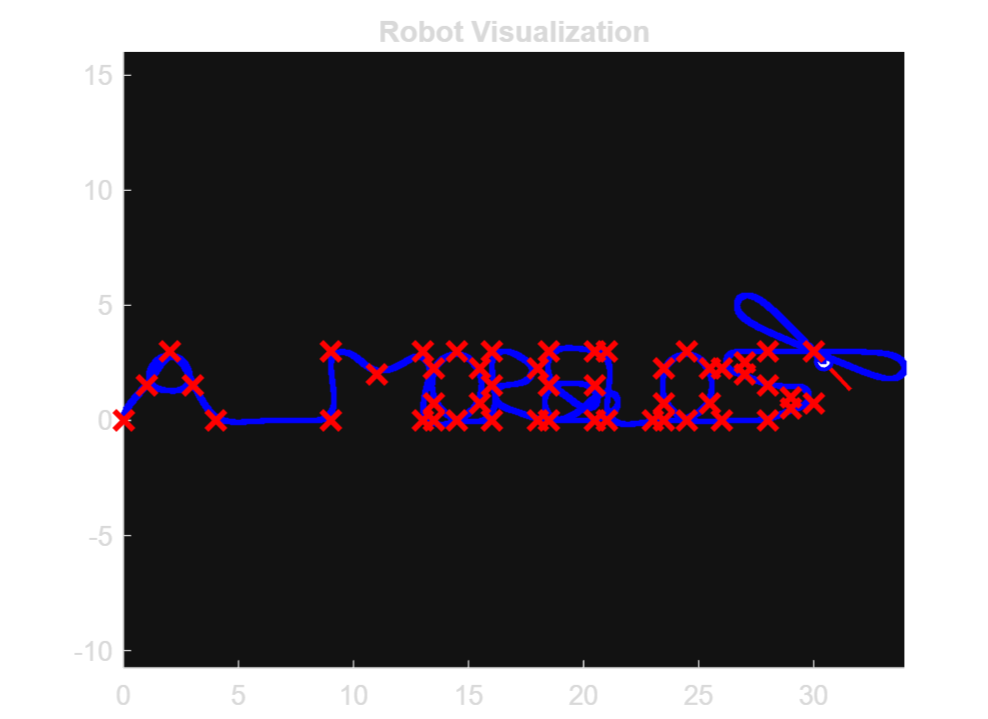

**Responder **las siguientes preguntas en base al procedimiento empleado para obtener las trayectorias propuestas:

**a) **¿Cuál fué el o los parámetros que se modifican para obtener una trayectoria recta? ¿Porqué?

En este caso las lineas rectas no fueron un problemas, pero si hubiera un problema y quisieramos ajustar el modelo, lo podemos hacer modificando la variable controller.DesiredLinearVelocity = 1;

**b)** ¿Cuál fué el o los parámetros que se modifican para obtener una trayectoria curva? ¿Porqué?

Para las trayectorias curavas se modifico la variable controller.MaxAngularVelocity = 5;  para obtener un giro mas cerrado ya que al darle una velocidad angular mas alta se obtienen vueltas mas cerradas

**c) **¿Cuál fué el o los parámetros que se modifican para obtener un giro? ¿Porqué?

Se modifica controller.LookaheadDistance = .8; ya que esta variable es la distancia a la el robo ve a delante para encontrar el siguiente landmark

**d) **¿Qué papel desempeña el vector del tiempo en la generación de la trayectoria?

El tiempo es necesario para que se ejecute la simulacion, sin embrago con una frecuencia mas pequeña la trayectoria se vera mas definida.

**e) **¿Cuáles fueron los parámetros que se ajustaron para obtener las dimensiones de las trayectorias deseadas?

Para la trayectoria se introdujeron todos los puntos donde se necesitaria un landmark para genera una letra en waypoints